## EX1

roots([0.4 -1.3 1]) % function to get roots of polynomials in case you are curious

ans =     2.0000
    1.2500


## EX4

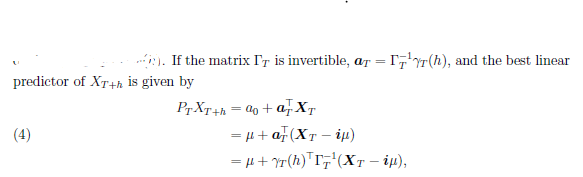

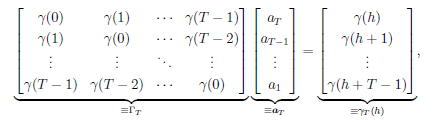

theta = - 0.5;

% INITIALIZING OBJECTS AS CELLS

a_i = {};
bigGamma = {};
smallGamma = {};

mspeA = zeros(4,1);

for (i = 1:4)
    bigGamma{i} = full(gallery('tridiag', i, theta/(1+theta^2), 1, theta/(1+theta^2)));
    smallGamma{i} = [theta/(1+theta^2) repelem(0,i-1)]';
    disp("a" + i)
    disp(bigGamma{i}\smallGamma{i})
    a_i{i} =bigGamma{i}\smallGamma{i};
    mspeA(i,1) = (1-smallGamma{i}'*inv(bigGamma{i})*smallGamma{i})*(1+theta^2);
end

a1


   -0.4000



a2


   -0.4762
   -0.1905



a3


   -0.4941
   -0.2353
   -0.0941



a4


   -0.4985
   -0.2463
   -0.1173
   -0.0469




mspeA

mspeA =     1.0500
    1.0119
    1.0029
    1.0007


%say i = 100
    bigGamma100 = full(gallery('tridiag', 100, theta/(1+theta^2), 1, theta/(1+theta^2)));
    smallGamma100 = [theta/(1+theta^2) repelem(0,100-1)]';
    a100 =bigGamma100\smallGamma100

a100 =    -0.5000
   -0.2500
   -0.1250
   -0.0625
   -0.0313
   -0.0156
   -0.0078
   -0.0039
   -0.0020
   -0.0010


    tail(a100)

   1.0e-27 *

   -0.1010
   -0.0505
   -0.0252
   -0.0126
   -0.0063
   -0.0031
   -0.0015
   -0.0006



## EX5

%% EX5

%1

load("data.mat")

fullSpreadTime = data.Date;
fullSpreadSeries = data.Spread;

S = timerange(datetime('01/01/2000','InputFormat','dd/MM/uuuu'), ...
    datetime('01/09/2022','InputFormat','dd/MM/uuuu'));
data = data(S,:);
tail(data)

       Date       LTINT    STINT    Spread
    __________    _____    _____    ______

    2022-01-31    1.88     0.07     0.0181
    2022-02-28    2.11     0.07     0.0204
    2022-03-31     2.5     0.17     0.0233
    2022-04-30    3.01     0.41      0.026
    2022-05-31    3.38        1     0.0238
    2022-06-30    3.77      1.6     0.0217
    2022-07-31    3.43     2.07     0.0136
    2022-08-31    3.43     2.31     0.0112



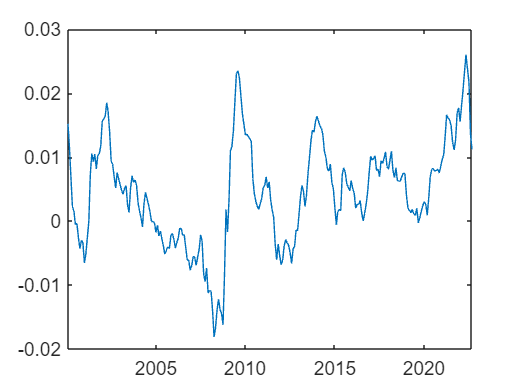


% Get number of periods
N = size(data,1);

plot(data.Date,data.Spread)

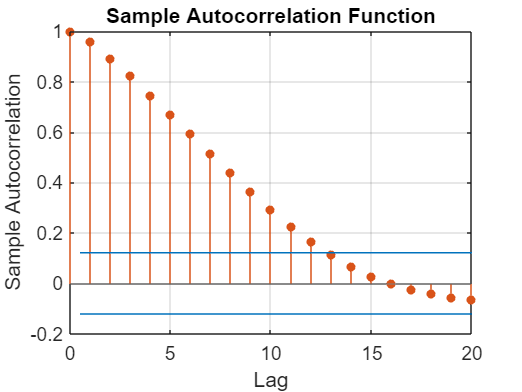


% Calculate ACF
ACF_spread=autocorr(data.Spread);
autocorr(data.Spread)

%2

meanSpread = mean(data.Spread);
demanedSpread = data.Spread-meanSpread;

dataRegression = lagmatrix(demanedSpread,0:4);

[beta_reg1,bint_reg1,res_reg1] = regress(dataRegression(:,1),dataRegression(:,2:5));

beta_reg1

beta_reg1 =     1.2814
   -0.4107
    0.2698
   -0.1984



% Roots of autorregresive polynomial
roots([flip(-beta_reg1') 1])

ans =   -0.5572 + 1.7286i
  -0.5572 - 1.7286i
   1.2840 + 0.0000i
   1.1898 + 0.0000i


abs(roots([flip(-beta_reg1') 1])) % Abs function returns the norm of each root (just absolute value for real numbers)

ans =     1.8162
    1.8162
    1.2840
    1.1898


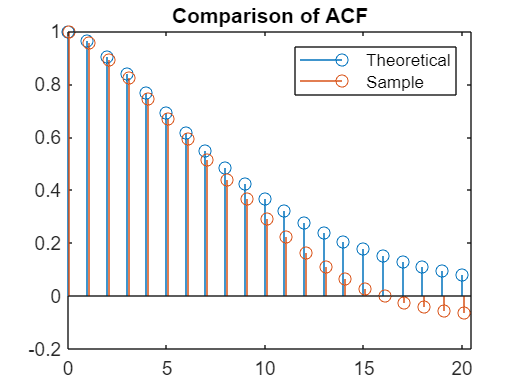

%3

% Get theoretical ACVF and ACF from acvf function

theoACVF=acvf([1;-beta_reg1],1,20);
theoACVF=theoACVF*var(res_reg1(5:end));
theoACF=theoACVF/(theoACVF(1));

sampleACF=autocorr(demanedSpread);
sampleACVF=autocorr(demanedSpread)*var(demanedSpread);

% Comparison of ACF

stem(0:20,theoACF) 
hold on 
stem((0:20)+.1,sampleACF)
xlim([0 20.5])
yline(0)
legend('Theoretical','Sample')
title('Comparison of ACF')
hold off

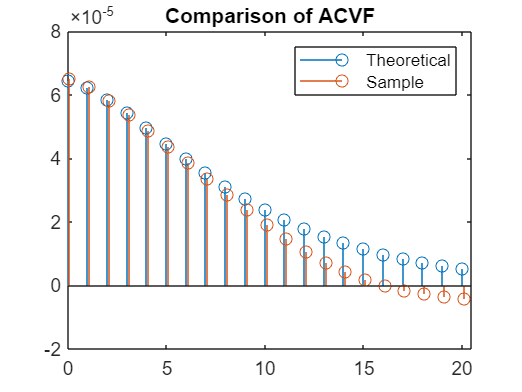


% Comparison of ACVF

stem(0:20,theoACVF) 
hold on 
stem((0:20)+.1,sampleACVF)
xlim([0 20.5])
yline(0)
legend('Theoretical','Sample')
title('Comparison of ACVF')
hold off

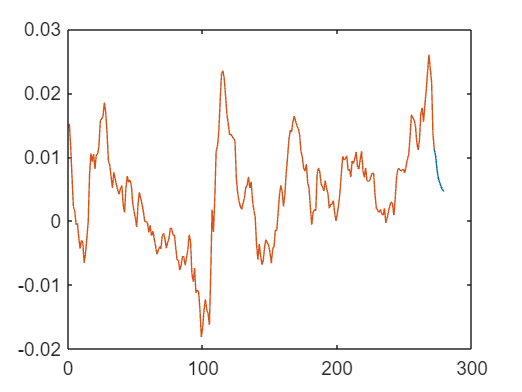


%4

% Get predicted values P_{T+H}
% Obtained recursevely from
% A_1*X_{T+H-1} + A_2*X_{T+H-2} + A_3*X_{T+H-3} + A_4*X_{T+H-4}
% Where X_{k} could be a prediction itself and not a data point

spreadOut = [demanedSpread;repelem(0,7)'];

for (i = 1:7)
    spreadOut(size(data,1)+i) = flip(spreadOut((size(data,1)+i-4):(size(data,1)+i-1)))'*beta_reg1;
end

toLevelSpreadOut = spreadOut + mean(data.Spread);

% Plot predicted values after T and data

plot(toLevelSpreadOut)
hold on
plot(data.Spread)
hold off


% Get MSPE values 

mspeEx5 = zeros(7,1);

% Estimate the variance of the underlying white noise from part 2

sigma2Hat = var(res_reg1(5:end,:));

for (i = 1:7)
    mspeEx5(i,1) = sigma2Hat*sum(polydiv(1,[1;-beta_reg1],i-1).^2);
end

mspeEx5

mspeEx5 = 1.0e-04 *

    0.0405
    0.1070
    0.1684
    0.2391
    0.3113
    0.3741
    0.4287


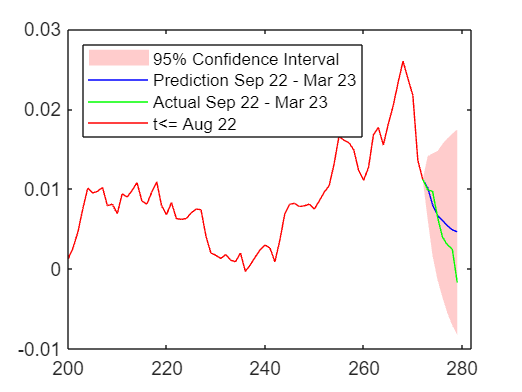


%5

% Get approximate 95% confidence interval

spreadOutCI = 1.96*sqrt([0;mspeEx5]).*[-ones(8,1) ones(8,1)]+spreadOut(size(data,1)+(0:7));
toLevelSpreadOutCI = spreadOutCI + mean(data.Spread);

% Plot 

figure
p = fill([size(data,1):(size(data,1)+7) (size(data,1)+7):-1:(size(data,1))],[toLevelSpreadOutCI(:,1)' flip(toLevelSpreadOutCI(:,2))'],'red');
p.FaceColor = [1 0.8 0.8];      
p.EdgeColor = 'none'; 
hold on
plot(toLevelSpreadOut,'b')
plot(fullSpreadSeries,'g')
plot(data.Spread,'r')
xlim([200 282])
legend('95% Confidence Interval','Prediction Sep 22 - Mar 23','Actual Sep 22 - Mar 23','t<= Aug 22','Location','northwest')
hold off